# Welding points 

## Problem statement

A Unimation Puma 560 robot is used to weld a folded tubes frame as it is shown in the next figures.

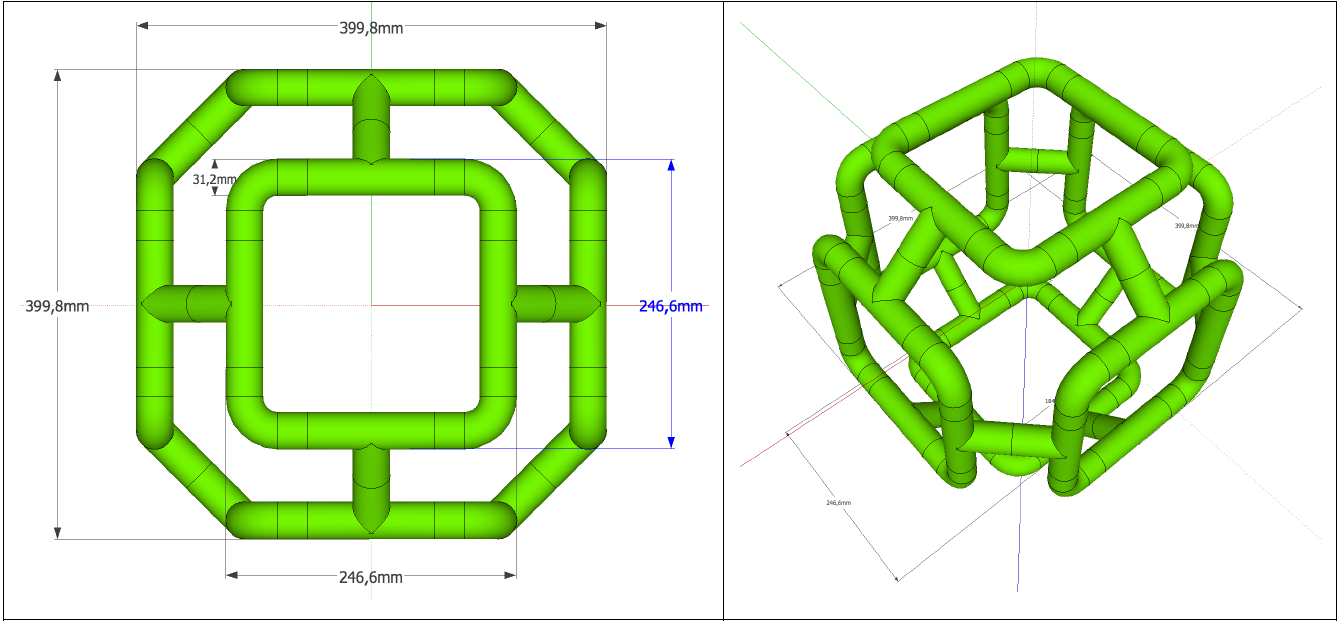

The task for the Puma 560 consists in welding the six folded squared tube among them. The welding trajectory can be assumed to as two orthogonal and intersecting cylinders with radius 𝑟 = 15.6mm. The trajectory to be followed by the welder can be parameterized as follows and it can be shown below:


$$p(t) = \left[ {\begin{array}{*{20}{c}}
  {x(t)} \\ 
  {y(t)} \\ 
  {z(t)} 
\end{array}} \right] = \left[ {\begin{array}{*{20}{c}}
  {r\cos (t)} \\ 
  {r\sin (t)} \\ 
  {\left[\kern-0.15em\left[ {r\cos (t)} 
 \right]\kern-0.15em\right]} 
\end{array}} \right];t \in \left[ {\begin{array}{*{20}{c}}
  0&{2\pi } 
\end{array}} \right]$$


## Visualize the result

open('24_sites_x32_points.fig')

## **Sketching the idea**

To obtain 32 welding point of two intersecting cylinder. 

### Cylinder Vertices/Faces 

Notice the scale 

load('F_V_cylinder.mat')
V_scale=[0.0156*V_cy(:,1) 0.0156*V_cy(:,2) V_cy(:,3)/40]

V_scale =     0.0156         0         0
    0.0156         0    0.0053
    0.0156         0    0.0105
    0.0156         0    0.0158
    0.0156         0    0.0211
    0.0156         0    0.0263
    0.0156         0    0.0316
    0.0156         0    0.0368
    0.0156         0    0.0421
    0.0156         0    0.0474


close all
clf
subplot(121)
h=patch('Faces',F_cy,'Vertices',V_cy);
set(h,'FaceColor','b','FaceAlpha',0.3,'EdgeColor','k')
view(14,41)
subplot(122)
V_scale=[0.0156*V_cy(:,1) 0.0156*V_cy(:,2) V_cy(:,3)/40]

V_scale =     0.0156         0         0
    0.0156         0    0.0053
    0.0156         0    0.0105
    0.0156         0    0.0158
    0.0156         0    0.0211
    0.0156         0    0.0263
    0.0156         0    0.0316
    0.0156         0    0.0368
    0.0156         0    0.0421
    0.0156         0    0.0474


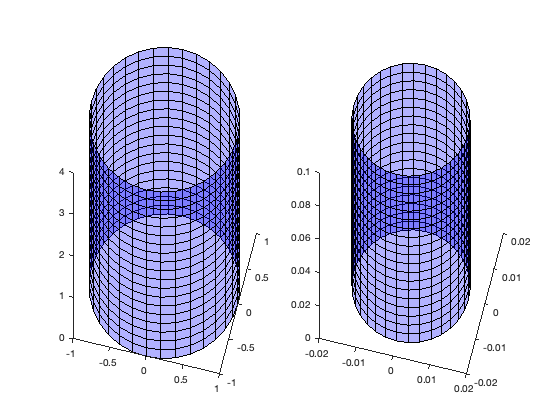

h=patch('Faces',F_cy,'Vertices',V_scale);
set(h,'FaceColor','b','FaceAlpha',0.3,'EdgeColor','k')
view(14,41)

### **Generating points**

r=15.6;
t=0:pi/16:2*pi;
cp0=[r*cos(t);r*sin(t);abs(r*cos(t));ones(1,length(t))]

cp0 =    15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000   -3.0434   -5.9699   -8.6669  -11.0309  -12.9709  -14.4125  -15.3003  -15.6000  -15.3003  -14.4125  -12.9709  -11.0309   -8.6669   -5.9699   -3.0434   -0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000
         0    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000   -3.0434   -5.9699   -8.6669  -11.0309  -12.9709  -14.4125  -15.3003  -15.6000  -15.3003  -14.4125  -12.9709  -11.0309   -8.6669   -5.9699   -3.0434   -0.0000
   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000
 

### **Plotting centered points**

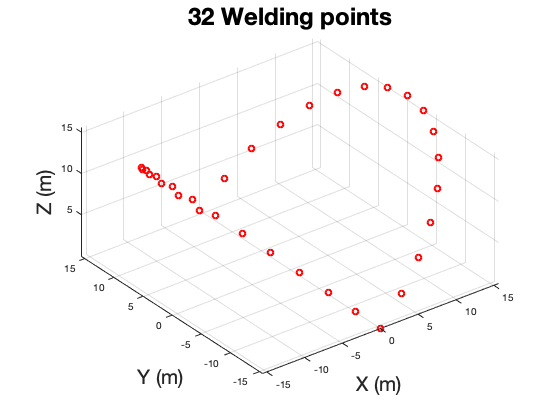

figure
scatter3(cp0(1,:),cp0(2,:),cp0(3,:),'r','LineWidth',2)
xlabel('X (m)','FontSize',20);
ylabel('Y (m)','FontSize',20);
zlabel('Z (m)','FontSize',20);
% Create title
title('32 Welding points','FontSize',24);
hold off
grid on;
axis equal;

### Centering two cylinders

Practice Operations: Translation, Rotations

## Conceptualize the solution

Continuing practicing till get a visualization like

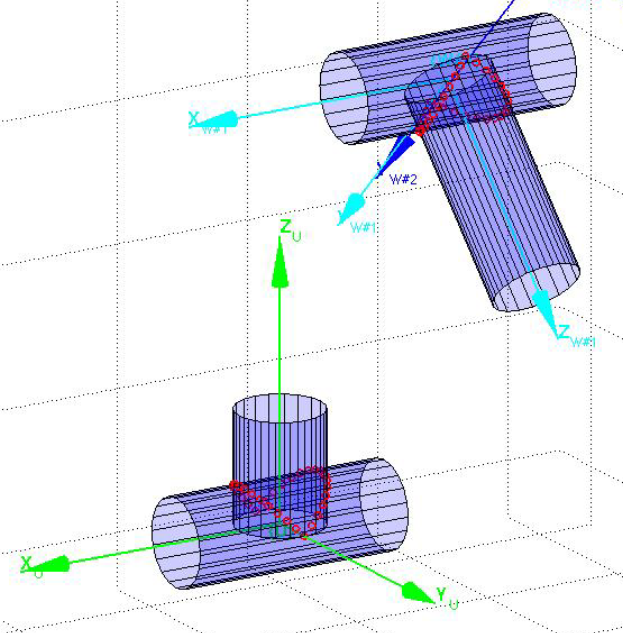

## Try one site

### Plot the folded tube frame

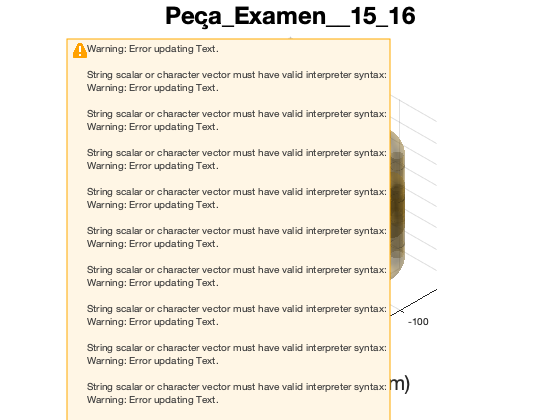

[V,F, N,name]=stlRead('welding_points.stl');
stlPlot(V,F,name)

### Soldering points of a site

You have to obtain similar as the given solution.